# Add a Preprocessing Function

Instructions are in the task pane to the left. Complete and submit each task one at a time. Do not edit. This code creates a datastore, imports data, and visualizes it.

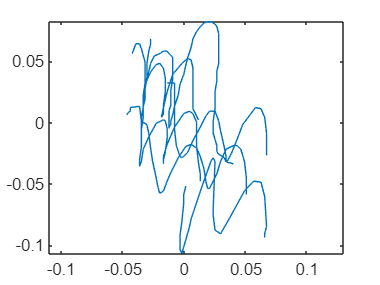

letterds = datastore("_M_.txt");
data = read(letterds);
data = scale(data);
plot(data.X,data.Y)
axis equal

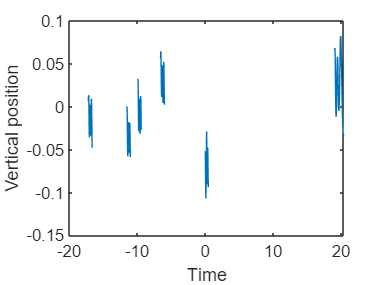

plot(data.Time,data.Y)
ylabel("Vertical position")
xlabel("Time")

## Task 2

To use a function as an input to another function, create a *function handle* by adding the `@` symbol to the beginning of the function name.

`transform``(``ds``,@``myfun``)`

A function handle is a reference to a function. Without the `@` symbol, MATLAB will interpret the function name as a call to that function.

**TASK2**

Use the `transform` function to create a transformed datastore called `preprocds`. This datastore should apply the `scale` function to the data referenced by `letterds`.

**Hint2**

Pass the datastore `letterds` and the function handle `@``scale` to the `transform` function. Assign the result to `preprocds`.

preprocds = transform(letterds,@scale)

preprocds =   TransformedDatastore with properties:

      UnderlyingDatastores: {matlab.io.datastore.TabularTextDatastore}
    SupportedOutputFormats: ["txt"    "csv"    "xlsx"    "xls"    "parquet"    "parq"    "png"    "jpg"    "jpeg"    "tif"    "tiff"    "wav"    "flac"    "ogg"    "mp4"    "m4a"]
                Transforms: {@scale}
               IncludeInfo: 0


## Task 3

The `scale` function should now be applied automatically whenever data is read from the `preprocds` datastore.

**TASK3**

Use the `readall` function to import all the data. Check that the preprocessing function was applied to each file by plotting the `Y` variable as a function of `Time`.

**Hint3**

Pass the transformed datastore `preprocds` to the `readall` function. Then pass the `Time` and `Y` variables of the resulting table to the `plot` function.

data = readall(preprocds)

data = 256×4 table
    Time         X           Y         P  
    _____    _________    _______    _____

        0     0.001116    -0.0517    0.042
    0.002     0.001116    -0.0527    0.255
    0.002     0.001116    -0.0527    0.255
    0.019    -0.000384    -0.0587     0.44
    0.027    -0.000384    -0.0657    0.569
    0.044    -0.001884    -0.0807    0.745
     0.06    -0.003384    -0.0917      0.8
     0.08    -0.003384    -0.1037    0.851
    0.094    -0.001884    -0.1067     0.88
    0.138     0.004116    -0.0857    0.894
    0.143     0.005616    -0.0787    0.896
    0.169     0.014616    -0.0517    0.899
    0.189     0.022116    -0.0307    0.923
    0.194     0.023616    -0.0287    0.931
    0.212     0.025116    -0.0317    0.995
    0.252     0.023616    -0.0707        1


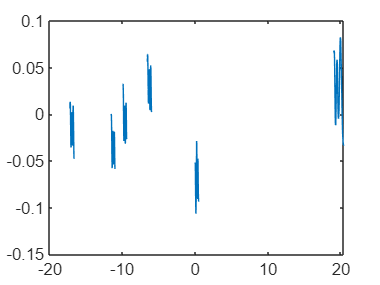

plot(data.Time,data.Y)

## Further Practice

## Tasks 1, 4, & 5

## Task 1 

You can add a custom function **at the end** of your script. For data preprocessing, the function should take the data returned from the datastore as input. It should return the transformed data as output.

`function` `dataout` `=` `functionName``(``datain``)`

    `% do something with datain`

    `dataout` `=` `...`

`end`

**TASK1**

Create a function called `scale` at the end of the script that performs the following operations:

`data.Time` `=` `(``data.Time` `-` `data.Time``(``1``))``/``1000``;`

`data.X` `=` `1.5``*``data.X``;`

Because these commands modify the variable `data` directly, your function should use `data` as both the input and output variable.

Note that the third line of the script calls the `scale` function. Your script won't run until this function has been created.

Also note that local functions must be at the end of a script. This means you will be editing the script sections out of order in this interaction. The section headings show which section of the script to edit in each task.

**Hint1**

At the end of the script, create a function with the function declaration `function` `data` `=` `scale``(``data``)`. Copy the given lines of code to the body of the function.

% function data = scale(data)
% data.Time = (data.Time - data.Time(1))/1000;
% data.X = 1.5*data.X;
% end

## Task 4

**TASK4**

Modify the `scale` function to subtract the mean position from both components:

`data.X` `=` `data.X` `-` `mean``(``data.X``)``;`

`data.Y` `=` `data.Y` `-` `mean``(``data.Y``)``;`

Note that this will introduce a problem that will make the plot appear blank. You will fix this in the next task.

**Hint4**

Add the given commands to the `scale` function.

% function data = scale(data)
% data.Time = (data.Time - data.Time(1))/1000;
% data.X = 1.5*data.X;
% data.X = data.X - mean(data.X);
% data.Y = data.Y - mean(data.Y);
% end

## Task 5

Any calculations (including the default use of functions such as `mean`) involving `NaN`s will result in `NaN`. This is important in machine learning, where you often have missing values in your data. In the handwriting data, a `NaN` occurs wherever the writer lifted the pen from the tablet.

You can use the `"omitnan"` option to have statistical functions like `mean` ignore missing values.

`mean``(``x``,``"omitnan"``)`

**TASK5**

Add the `"omitnan"` option to the calls to `mean` in the `scale` function.

**Hint5**

In the `scale` function, change `mean``(``data.X``)` and `mean``(``data.Y``)` to `mean``(``data.X``,``"omitnan"``)` and `mean``(``data.Y``,``"omitnan"``)`

function data = scale(data)
data.Time = (data.Time - data.Time(1))/1000;
data.X = 1.5*data.X;
data.X = data.X - mean(data.X,"omitnan");
data.Y = data.Y - mean(data.Y,"omitnan");
end